clc; close all; clear variables

## **DYNAMICS AND CONTROL OF VEHICLES AND ROBOTS**

## Intro

In this script the telemetry data from the P1 experimental vehicles are loaded. This Matlab Live Script can be used as the structure for your project script. 

Click "Save as..." and save this script as .m in order to obtain a classic Matlab script.

## Load Vehicle Parameters

The script loads the vehicle main parameters in the `vehicle` struct. See the script `p1_parameters.m` for comments about parameters names and units.

p1_parameters

## Load Datasets

The following test are available.

**DATASET NAME DESCRIPTION**

RAMP_STEER_L Left-hand ramp steer 10 m/s

RAMP_STEER_R Right-hand ramp steer 10 m/s

SINE_STEER_IS Sine wave steering at increasing speeds

SP_100FT_CR_IS_CCW Steering pad 100 ft circle constant radius increasing speed counter-clockwise

SP_100FT_CR_IS_CW Steering pad 100 ft circle constant radius increasing speed clockwise

STRAIGHT_LINE_0 Straight line at constant speed

STRAIGHT_LINE_1 Straight line in one direction

STRAIGHT_LINE_2 Straight line in the opposite direction

STEP_STEER Step steer

The loaded variable is a struct cointaing the following telemetry signals:

% DATA			UNITS		DESCRIPTION
% time                  s               acquisition time
% yaw			rad		yaw angle
% yaw_rate		rad/s 		yaw rate at COM
% roll			rad		roll at COM
% roll_rate		rad/s 		roll rate at COM
% long_vel		m/s 		longitudinal velocity of the COM
% lat_vel		m/s 		lateral velocity of the COM
% axG			m/s^2		longitudinal acceleration of the COM
% ayG			m/s^2 		lateral acceleration of the COM
% body_slip		rad		vehicle side slip angle (at COM)
% omega_FL		rad/s 		wheel angular speed
% omega_FR		rad/s 		wheel angular speed
% omega_RL		rad/s 		wheel angular speed
% omega_RR		rad/s 		wheel angular speed
% front_slip_angle      rad		equivalent (single track) slip angle at front axle
% rear_slip_angle       rad		equivalent (single track) slip angle at rear axle
% Fx_FL			N		tyre longitudinal force
% Fy_FL			N		tyre lateral force
% Fz_FL			N		tyre vertical force
% Fx_FR			N		tyre longitudinal force
% Fy_FR			N		tyre lateral force
% Fz_FR			N		tyre vertical force
% x_pos			m		COM position x coordinate (from GPS)
% y_pos			m		COM position y coordinate (from GPS)
% z_pos			m		COM position z coordinate or altitude (from GPS)
% delta_L		rad		steering angle of the front left wheel
% delta_R		rad		steering angle of the front right wheel
% delta_HW 		rad		handwheel steering angle

## Longitudinal Practical Slip

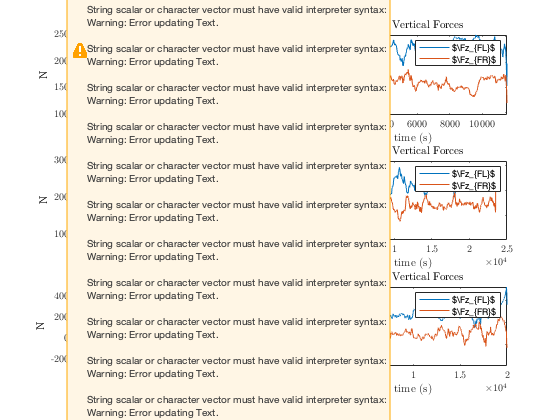

load("Dataset/STRAIGHT_LINE_0.mat");
load("Dataset/STRAIGHT_LINE_1.mat");
load("Dataset/STRAIGHT_LINE_2.mat");

close all
load("roll_rad.mat","R_dyn")
ft = fittype('Kx*x'); 
fit_kx_FL_1 = fit(abs(mean([STRAIGHT_LINE_1.long_vel])),mean(STRAIGHT_LINE_1.long_vel-STRAIGHT_LINE_1.omega_FL*R_dyn),ft,'StartPoint',0);
kx_FL_1 = fit_kx_FL_1.Kx;
fit_kx_FR_1 = fit(abs(mean([STRAIGHT_LINE_1.long_vel])),mean(STRAIGHT_LINE_1.long_vel-STRAIGHT_LINE_1.omega_FR*R_dyn),ft,'StartPoint',0);
kx_FR_1 = fit_kx_FR_1.Kx;

ft = fittype('Kx*x'); 
fit_kx_FL_2 = fit(abs(mean([STRAIGHT_LINE_2.long_vel])),mean(STRAIGHT_LINE_2.long_vel-STRAIGHT_LINE_2.omega_FL*R_dyn),ft,'StartPoint',0);
kx_FL_2 = fit_kx_FL_2.Kx;
fit_kx_FR_2 = fit(abs(mean([STRAIGHT_LINE_2.long_vel])),mean(STRAIGHT_LINE_2.long_vel-STRAIGHT_LINE_2.omega_FR*R_dyn),ft,'StartPoint',0);
kx_FR_2 = fit_kx_FR_2.Kx;

figure
subplot(3,2,1)
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fx_FL,500),'DisplayName','$\Fx_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fx_FR,500),'DisplayName','$\Fx_{FR}$')
xlabel('time (s)');ylabel('N');
title('Front Wheels Longitudinal Forces');
legend

subplot(3,2,2)
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fz_FL,500),'DisplayName','$\Fz_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fz_FR,500),'DisplayName','$\Fz_{FR}$')
xlabel('time (s)');ylabel('Fz (N)');
title('Front Vertical Forces');
legend

subplot(3,2,3)
plot(smooth(STRAIGHT_LINE_1.time,STRAIGHT_LINE_1.Fx_FL,500),'DisplayName','$\Fx_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_1.time,STRAIGHT_LINE_1.Fx_FR,500),'DisplayName','$\Fx_{FR}$')
xlabel('time (s)');ylabel('N');
title('Front Wheels Longitudinal Forces');
legend

subplot(3,2,4)
plot(smooth(STRAIGHT_LINE_1.time,STRAIGHT_LINE_1.Fz_FL,500),'DisplayName','$\Fz_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_1.time,STRAIGHT_LINE_1.Fz_FR,500),'DisplayName','$\Fz_{FR}$')
xlabel('time (s)');ylabel('Fz (N)');
title('Front Vertical Forces');
legend
subplot(3,2,5)
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fx_FL,500),'DisplayName','$\Fx_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fx_FR,500),'DisplayName','$\Fx_{FR}$')
xlabel('time (s)');ylabel('N');
title('Front Wheels Longitudinal Forces');
legend
subplot(3,2,6)
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fz_FL,500),'DisplayName','$\Fz_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fz_FR,500),'DisplayName','$\Fz_{FR}$')
xlabel('time (s)');ylabel('Fz (N)');
title('Front Vertical Forces');
legend

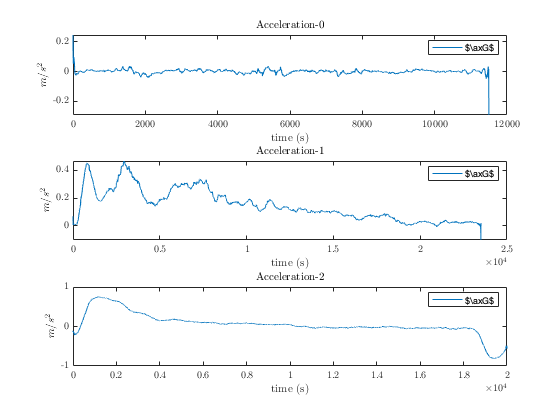


%Check accelerations
figure
subplot(3,1,1)
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.axG,500),'DisplayName','$\axG$')
xlabel('time (s)');ylabel('$m/s^{2}$');
title('Acceleration-0');
legend

subplot(3,1,2)
plot(smooth(STRAIGHT_LINE_1.time,STRAIGHT_LINE_1.axG,500),'DisplayName','$\axG$')
xlabel('time (s)');ylabel('$m/s^{2}$');
title('Acceleration-1');
legend

subplot(3,1,3)
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.axG,500),'DisplayName','$\axG$')
xlabel('time (s)');ylabel('$m/s^2$');
title('Acceleration-2');
legend